clear

Read in AC Load (from Menzies Building)

data = readtable("dataCleaned.csv");

data = renamevars(data, "ptot","AC");      %Rename the AC electrical load to AC
summary(data)

Variables:

    tstamp: 8760×1 datetime

        Properties:
            Description:  tstamp
        Values:

            Min       01-Jan-2022 00:00:00
            Median    02-Jul-2022 11:30:00
            Max       31-Dec-2022 23:00:00

    date: 8760×1 double

        Properties:
            Description:  date
        Values:

            Min           1   
            Median      183   
            Max         365   

    day: 8760×1 double

        Properties:
            Description:  day
        Values:

            Min          1    
            Median       4    
            Max          7    

    time: 8760×1 double

        Properties:
            Description:  time
        Values:

            Min             0 
            Median    0.47917 
            Max       0.95833 

    week_number: 8760×1 double

        Properties:
            Description:  week_number
        Values:

        

%Removing date (have tstamp),
% Removing time(have working hours and daytime)
%Removing day (have Weekday, Sat, Sun)

data = removevars(data,["tstamp","week_number","epoch_timestamp","month"]);


data = data(:, ["AC", "time", "DC", "date", "day", "wrkHr","dayTime","Off_Peak","Peak","Standard","weekDay"])

data = 8760×11 table
      AC        time       DC     date    day    wrkHr    dayTime    Off_Peak    Peak    Standard    weekDay
    ______    ________    ____    ____    ___    _____    _______    ________    ____    ________    _______

    96.855           0    52.2     1       6       0         0          1         0         0           0   
    97.053    0.041667      52     1       6       0         0          1         0         0           0   
    97.229    0.083333    52.2     1       6       0         0          1         0         0           0   
    96.859       0.125    52.2     1       6       0       

summary(data)

Variables:

    AC: 8760×1 double

        Properties:
            Description:  ptot
        Values:

            Min         79.12 
            Median     165.23 
            Max        304.46 

    time: 8760×1 double

        Properties:
            Description:  time
        Values:

            Min             0 
            Median    0.47917 
            Max       0.95833 

    DC: 8760×1 double

        Properties:
            Description:  DC
        Values:

            Min         35.6  
            Median      70.7  
            Max        211.7  

    date: 8760×1 double

        Properties:
            Description:  date
        Values:

            Min           1   
            Median      183   
            Max         365   

    day: 8760×1 double

        Properties:
            Description:  day
        Values:

            Min          1    
            Median       4    
        

**Train model**

%Need to get rid of date time. Think Imma keep Hour

labels = data.Properties.VariableNames;

%data=normalize(data(:,["AC","DC", "day", "time"] ));

% minAC = min(data.AC(:))
% minDC = min(data.DC(:))
% minDay = min(data.day(:));
% minTime = min(data.time(:));
% 
% maxAC = max(data.AC(:))
% maxDC = max(data.DC(:))
% maxDay = max(data.day(:));
% maxTime = max(data.time(:));
% 
% data.AC = (data.AC(:) - minAC)/(maxAC-minAC);
% data.DC = (data.DC(:) -minDC)/(maxDC - minDC);
% data.day = (data.day(:) - minDay)/(maxDay - minDay);
% data.time = (data.time(:) -minTime)/(maxTime - minTime);

data = removevars(data,["AC","date","day","dayTime","weekDay"])

data = 8760×6 table
      time       DC     wrkHr    Off_Peak    Peak    Standard
    ________    ____    _____    ________    ____    ________

           0    52.2      0         1         0         0    
    0.041667      52      0         1         0         0    
    0.083333    52.2      0         1         0         0    
       0.125    52.2      0         1         0         0    
     0.16667    52.2      0         1         0         0    
     0.20833    51.5      0         1         0         0    
        0.25    50.9      0         1         0         0    
     0.29167      49      0         1         0         0    
     0.33333    49.3      0         1         0         0    
       0.375    50.9      0         1         0         0    
     0.41667    50.4      0    

summary(data)

Variables:

    time: 8760×1 double

        Properties:
            Description:  time
        Values:

            Min             0 
            Median    0.47917 
            Max       0.95833 

    DC: 8760×1 double

        Properties:
            Description:  DC
        Values:

            Min         35.6  
            Median      70.7  
            Max        211.7  

    wrkHr: 8760×1 double

        Properties:
            Description:  wrkHr
        Values:

            Min          0    
            Median       0    
            Max          1    

    Off_Peak: 8760×1 double

        Properties:
            Description:  Off-Peak
        Values:

            Min          0    
            Median       1    
            Max          1    

    Peak: 8760×1 double

        Properties:
            Description:  Peak
        Values:

            Min          0    
            Median       

For lstm I want to break the time series up into shorter batches

Batch size 7days. 

Create cell array with a cell for each batch

Each batch is 7days of observations (rows are variables and columns are time steps)

numDays = 35;

height = ceil(size(data(:,1))/(numDays*24));
dataCell = cell(height(1), 1);

for i = 1:numel(dataCell)
    %Get the range of rows that you need for this batch
    startIdx = (i-1)*numDays*24 + 1;
    endIdx   = min(i*numDays*24, size(data(:,1)));
    %Store the batch in an array
    currentBatch = table2array(data(startIdx:endIdx, :));
    %transpose array so that columns are timesteps
    currentBatch = transpose(currentBatch);
    %Store in cell array
    dataCell{i} = currentBatch;
end


Split data for Training and testing

numObservations = numel(dataCell);
perctSplit = 0.7

perctSplit = 0.7000


idxTrain = 1:floor(perctSplit*numObservations);
idxTest = floor(perctSplit*numObservations)+1:numObservations;
dataTrain = dataCell(idxTrain);
dataTest = dataCell(idxTest);

To forecast the values of future time steps of a sequence, specify the targets as the training sequences with values shifted by one time step. In other words, at each time step of the input sequence, the LSTM neural network learns to predict the value of the next time step. The predictors are the training sequences without the final time step.

**NOTE Try to change TTrain to only hold the future values of AC and DC since those are the values I am interested in?**

for n = 1:numel(dataTrain)
    %select batches one at a time.
    X = dataTrain{n}; 
    %Set the full sequence minus the last value as the predictors 
    XTrain{n} = X(:,1:end-1);
    %Set the Sequence but one step forward as the targets
    TTrain{n} = X(:,2:end);
end 

%Do the same for the test data
for n  = 1:numel(dataTest);
    X = dataTest{n};
    XTest{n} = X(:,1:end-1);
    TTest{n} = X(:,2:end);
end

We need to normailse the data to have a zero mean and unit variance. 

Note, Use the same mean and std deviation that you calculated on the training data on the test data. 

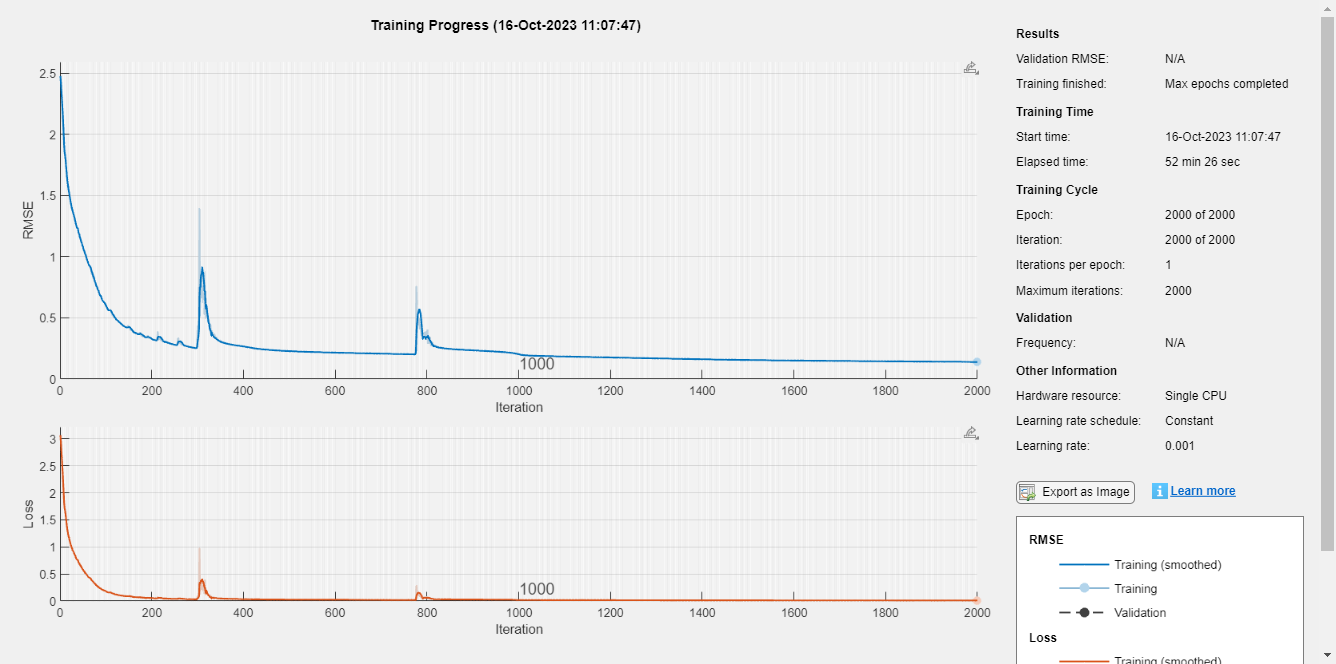

%Mean of training 
meanX = mean(cat(2,XTrain{:}),2);
sigmaX = std(cat(2,XTrain{:}),0,2);
%Mean of training Targets
meanT = mean(cat(2,TTrain{:}),2);
sigmaT = std(cat(2,TTrain{:}),0,2);

%apply to the training data
for n = 1:numel(XTrain)
    XTrain{n} = (XTrain{n}-meanX)./sigmaX;
    TTrain{n} = (TTrain{n}-meanT)./sigmaT;
end
%apply to the test data
for n = 1:numel(XTest)
    XTest{n} = (XTest{n}-meanX)./sigmaX;
    %TTest{n} = (TTest{n}-meanT)./sigmaT;
end

numChannels = size(dataCell{1},1); 

layersDC = [
    sequenceInputLayer(numChannels)
    lstmLayer(128)
    lstmLayer(128)
    lstmLayer(128)

    fullyConnectedLayer(numChannels)
    regressionLayer];


options = trainingOptions("adam", ...
    MaxEpochs=2000, ...
    SequencePaddingDirection="left", ...    
    Plots="training-progress", ...
    Verbose=0);

netDC = trainNetwork(XTrain,TTrain,layersDC,options);

**Test Network **

using the Test data and the trained net to make predictions.

predsDC = predict(netDC, XTest, SequencePaddingDirection="left");

Undo the standardisation on the predictions

for n = 1:numel(predsDC)
    predsDC{n} = (predsDC{n}.*sigmaT)+meanT;
end

To test the RMSE

for i = 1:size(predsDC,1)
    for k = 1:size(predsDC{1}(:,1))
        rmse(i,k) = sqrt(mean((predsDC{i}(k,:) - TTest{i}(k,:)).^2,"all"));
        mape(i,k) =   mean(abs((TTest{i}(k,:)-predsDC{i}(k,:))./TTest{i}(k,:)),"all")*100;
    end
end

for idxBatch = 1:numel(XTest)

figure
plot(TTest{idxBatch}(1,:));
hold on
plot(predsDC{idxBatch}(1,:));
hold off
legend("Actual AC", "Predictions AC");
title("AC prediction testBatch: " + idxBatch)

figure
plot(TTest{idxBatch}(3,:));
hold on
plot(predsDC{idxBatch}(3,:));
hold off
legend("Actual DC", "Predictions DC");
title("DC prediction test Batch: " + idxBatch)

end


figure
subplot(1,3,1)
histogram(mape(:,1))
title("AC MAPE " + mean(mape(:,1)) +"%" )
subplot(1,3,2)
plot(mape(:,1))
subplot(1,3,3)
bar(mape(:,1))

figure

subplot(1,3,1)
histogram(rmse(:,1))
title("AC RMSE" + mean(rmse(:,1)))
subplot(1,3,2)
plot(rmse(:,1))
subplot(1,3,3)
bar(rmse(:,1))



figure
subplot(1,3,1)
histogram(mape(:,3))
title("DC MAPE " + mean(mape(:,3)) +"%" )
subplot(1,3,2)
plot(mape(:,3))
subplot(1,3,3)
bar(mape(:,3))


figure
subplot(1,3,1)
histogram(rmse(:,3))
title("DC RMSE" + mean(rmse(:,3)))
subplot(1,3,2)
plot(rmse(:,3))
subplot(1,3,3)
bar(rmse(:,3))

**Closed loop forcasting to predict full day ahead :)**

Predict values **t ** through to **t+k ** when you have data collected for steps **1 ** through to **t-1;**

timeStep = 1;
numel(XTest)

ans = 4

idx=1;
X = [];
T=  [];
for i = 1:(numel(XTest))
    X = [X (XTest{i}(:,:))];
    T = [T (TTest{i}(:,:))];
end
   for j = 1:(floor(length(X(1,:))/timeStep)-ceil(24/timeStep))
        netDC = resetState(netDC);
        offset =  j*timeStep+1;
        [netDC,Z] = predictAndUpdateState(netDC,X(:,1:offset));
        
        numPredictionTimeSteps = 24;
        Xt = Z(:,offset);
        Y = zeros(numChannels, numPredictionTimeSteps); % the 2 is for the 2 output channels
        
        for t = 1:numPredictionTimeSteps
            [netDC,Y(:,t)] = predictAndUpdateState(netDC,Xt);
            Xt = Y(:,t);
        end
        
        %Undo Normalisation
        Y = (Y.*sigmaT)+meanT;
        numTimeSteps = offset+numPredictionTimeSteps-1;
        % 
        % figure
        % t=tiledlayout(2,1);
        % title(t, "Day ahead forecasting for Electrical load. BATCH NO: " + idx + " OFFSET: " +offset)
        % 
        % nexttile 
        % plot(T(1,1:offset))
        % hold on 
        % plot(offset:numTimeSteps,[T(1,offset) Y(1,:)],'--') 
        % plot( offset:numTimeSteps, T(1,offset:numTimeSteps),'r')
        % ylabel("AC day ahead forcast")
        % legend("Input","24h Forecast","24hr Actual","Location","northwest")
        % 
        % nexttile 
        % plot(T(3,1:offset))
        % hold on 
        % plot(offset:numTimeSteps,[T(3,offset) Y(3,:)],'--')
        % plot(offset:numTimeSteps, T(3,offset:numTimeSteps),'r')
        % ylabel("DC day ahead forcast")
        % legend("Input","24hr Forecast","24hr Actual","Location","northwest")

 

        for i = 1:size(Y(:,1))
                rmse(j,i) = mean((Y(i,:) - T(i,offset:numTimeSteps)).^2,"all");
                mape(j,i) =   mean(abs(T(i,offset:numTimeSteps)-Y(i,:))./T(i,offset:numTimeSteps),"all")*100;
        end

        for i = 1:size(Y(:,1))
                rmsePerHr(j,i,:) = (T(i,offset:numTimeSteps)-Y(i,:)).^2;
                mapePerHr(j,i,:) =   abs(T(i,offset:numTimeSteps)-Y(i,:))./T(i,offset:numTimeSteps)*100;
        end

        intAbsError(j)   = trapz(abs(T(2,offset:numTimeSteps)-Y(2,:)))/trapz(T(2,offset:numTimeSteps))*100;
        intAbsError2(j)   = (abs(trapz(T(2,offset:numTimeSteps))-trapz(Y(2,:))))/trapz(T(2,offset:numTimeSteps))*100;
        intRmse(j)       = ((trapz(T(2,offset:numTimeSteps)-Y(2,:))/24)^2);
   end



 
   netDC = resetState(netDC);
   offset =  96;
   [netDC,Z] = predictAndUpdateState(netDC,X(:,1:offset));

   numPredictionTimeSteps = 24;
   numTimeSteps = offset+numPredictionTimeSteps-1;
   Xt = Z(:,offset);
   Y = zeros(numChannels, numPredictionTimeSteps); % the 2 is for the 2 output channels
   for t = 1:numPredictionTimeSteps
       [netDC,Y(:,t)] = predictAndUpdateState(netDC,Xt);
       Xt = Y(:,t);
   end
       
   testAct = T(2, offset:numTimeSteps)

testAct =    47.0000   45.7000   46.3000   46.3000   47.3000   46.4000   63.4000  116.1000  149.9000  160.4000  163.3000  154.6000  162.5000  148.7000  149.9000  139.1000   96.7000   78.7000   64.6000   59.4000   53.8000   52.2000   51.8000   47.7000


   test = X(2, 60:offset).*sigmaX(2) +meanX(2)

test =   165.4000  171.9000  166.3000  142.9000  112.7000   82.6000   65.3000   61.0000   62.3000   59.6000   58.7000   58.0000   54.5000   52.7000   57.4000   61.9000   61.4000   61.7000   64.3000   81.0000  124.4000  164.2000  175.0000  165.1000  156.4000  164.9000  161.1000  155.5000  136.1000  103.0000   79.9000   72.9000   63.2000   58.5000   59.0000   56.5000   49.7000


   testPreds = Y(2,:).*sigmaT(2)+meanT(2)

testPreds =    52.8078   54.2068   54.6589   57.1855   58.9052   78.9673  132.1440  163.9624  162.9796  172.0918  173.5260  175.6152  162.4042  157.6929  144.9476  107.4062   89.3732   82.1042   77.4930   72.1745   66.4941   60.8449   59.1051   60.9225


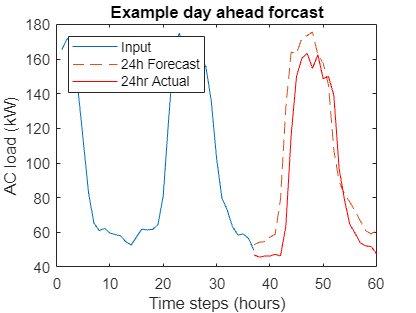

   
   % plot(offset:numTimeSteps,[T(1,offset) Y(1,:)],'--') 
        % plot( offset:numTimeSteps, T(1,offset:numTimeSteps),'r')
   plot(test)
   hold on 
   plot(offset-59:numTimeSteps-59, testPreds, '--')
   plot(offset-59:numTimeSteps-59, testAct, 'r')
   hold off
   ylabel("AC load (kW)")
   xlabel("Time steps (hours)")
   title("Example day ahead forcast")
   legend("Input","24h Forecast","24hr Actual","Location","northwest")


  testAct = T(2, offset:numTimeSteps)

testAct =    47.0000   45.7000   46.3000   46.3000   47.3000   46.4000   63.4000  116.1000  149.9000  160.4000  163.3000  154.6000  162.5000  148.7000  149.9000  139.1000   96.7000   78.7000   64.6000   59.4000   53.8000   52.2000   51.8000   47.7000


  testPreds = Y(2,:).*sigmaT(2)+meanT(2)

testPreds =    52.8078   54.2068   54.6589   57.1855   58.9052   78.9673  132.1440  163.9624  162.9796  172.0918  173.5260  175.6152  162.4042  157.6929  144.9476  107.4062   89.3732   82.1042   77.4930   72.1745   66.4941   60.8449   59.1051   60.9225


  MAPE =  abs(testAct-testPreds)./(testAct)*100

MAPE =    12.3570   18.6145   18.0538   23.5108   24.5354   70.1882  108.4290   41.2252    8.7256    7.2892    6.2621   13.5933    0.0589    6.0477    3.3038   22.7849    7.5769    4.3255   19.9582   21.5059   23.5950   16.5612   14.1025   27.7201


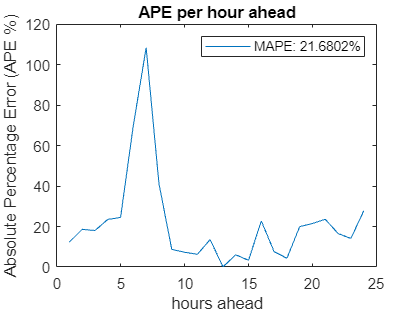


  figure
        plot(1:24, MAPE);
        legend("MAPE: " + mean(MAPE) + "%" )
        title("APE per hour ahead")
        xlabel("hours ahead")
        ylabel("Absolute Percentage Error (APE %)")


  meanMAPE = mean(MAPE)

meanMAPE = 21.6802


  intAct = trapz(testAct)

intAct = 2.1444e+03

  intAbsBetween = trapz(abs(testAct-testPreds))

intAbsBetween = 364.8354


intMAPE = (intAbsBetween / intAct )*100

intMAPE = 17.0130

        intMape = mean(intAbsError)

intMape = 23.4657

        intMape2 = mean(intAbsError2)

intMape2 = 18.2362


       intRmse = sqrt(mean(intRmse))

intRmse = 17.7545

        DCrmseMean = sqrt(mean(rmsePerHr(:,2,:),"all"))

DCrmseMean = 27.6020

        for i = 1:24
       % hourlyACrmse(i) = sqrt(mean(rmsePerHr(:,1,i),"all"));
        hourlyDCrmse(i) = sqrt(mean(rmsePerHr(:,2,i),"all"));
       % hourlyACmape(i) = mean(mapePerHr(:,1,i),"all");
        hourlyDCmape(i) = mean(mapePerHr(:,2,i),"all");
        end

#### Sace DC rmse and mape

        save('LSTM_DC', "hourlyDCmape","hourlyDCrmse",'DCrmseMean','intMape', 'intRmse')

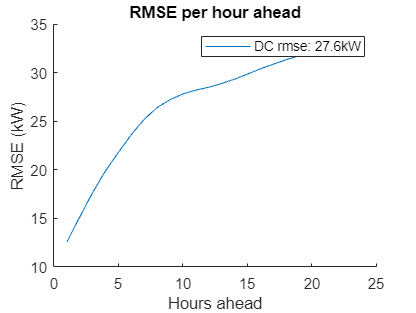

       figure
       % plot(1:24, hourlyACrmse);
        hold on
        plot(1:24,hourlyDCrmse);
        hold off
        legend("DC rmse: "+ round(DCrmseMean,2)+"kW")
        title("RMSE per hour ahead")
        xlabel("Hours ahead")
        ylabel("RMSE (kW)")

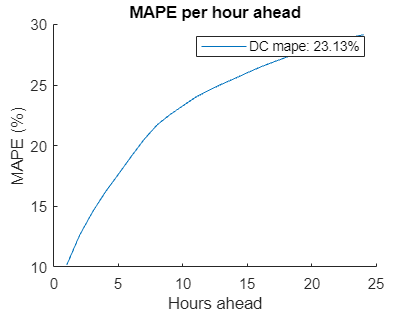

figure
        %plot(1:24, hourlyACmape);
        hold on
        plot(1:24,hourlyDCmape);
        hold off
        legend( "DC mape: "+ round(mean(hourlyDCmape),2)+"%")
        title("MAPE per hour ahead")
        xlabel("Hours ahead")
        ylabel("MAPE (%)")



        %display("AC MAPE: " + mean(mape(:,1))+"%")
        %display("AC RMSE: " + sqrt(mean(rmse(:,1)))+" kW")
        display("DC MAPE: " + mean(hourlyDCmape)+"%")

    "DC MAPE: 23.1278%"



        display("DC RMSE: " + DCrmseMean+" kW")

    "DC RMSE: 27.602 kW"

